# **Εργασία 3**

**Ονοματεπώνυμο: Εμμανουηλίδης Κωνσταντίνος**

**Α.Μ.: 57315**

### **Ερώτημα Α**

Ο σκοπός του πρώτου ερωτήματος είναι ο έλεγχος του ψηφιακού εφέ tube distortion για διάφορες παραμέτρους της ρουτίνας που το υλοποιεί. Η λειτουργία του εφέ θα εξεταστεί σε δύο διαφορετικά αρχεία ήχου για τις ίδιες παραμέτρους και στο τέλος θα καταγραφούν τα αποτελέσματα για το κάθε αρχείο ήχου.

Αρχικά, εισάγουμε τα αρχεία ήχου:

clear;
clc;
[x1,Fs] = audioread("guitar1.wav");
[x2,Fs] = audioread("vocals.wav");

Εφαρμόζουμε τη συνάρτηση tube_dist() στο πρώτο αρχείο ήχου για τις διάφορες τιμές παραμέτρων και παράγουμε το φασματογράφημα κάθε ηχητικού αποτελέσματος:

Q = [-0.2, -0.2, -0.2, 0]; 
dist = 8;
Gain = [1, 10, 20, 5];
results1 = zeros(132000,4);
% Apply tube distortion effect
for i=1:4
    results1(:,i) = tube_dist(x1,Q(i),dist,Gain(i)); 
end

% Create spectrograms
figure
s0 = subplot(3,2,1);
suptitle('Spectrograms for guitar.wav')
specgram(x1);
s1 = subplot(3,2,3);
specgram(results1(:,1));
s2 = subplot(3,2,4);
specgram(results1(:,2));
s3 = subplot(3,2,5);
specgram(results1(:,3));
s4 = subplot(3,2,6);
specgram(results1(:,4));

% Add titles to subplots
title(s0, 'Initial sound waveform')
title(s1, '1st Set of Parameters') 
title(s2, '2nd Set of Parameters')
title(s3, '3rd Set of Parameters')
title(s4, '4th Set of Parameters')

% Uncomment to listen the result
% soundsc(x1,16000);
% soundsc(results1(:,1),16000);
% soundsc(results1(:,2),16000);
% soundsc(results1(:,3),16000);
% soundsc(results1(:,4),16000);

Αντίστοιχα, εφαρμόζουμε την παραπάνω διαδικασία για το αρχείο ήχου vocal.wav:

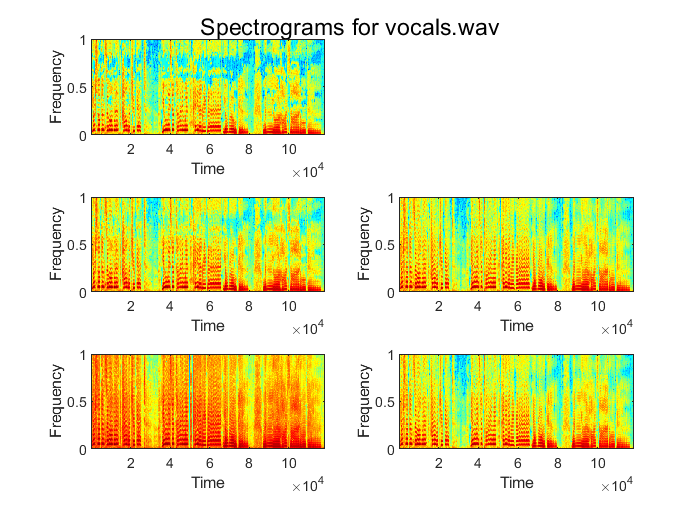

Q = [-0.2, -0.2, -0.2, 0]; 
dist = 8;
Gain = [1, 10, 20, 5];
results2 = zeros(236600,4);
% Apply tube distortion effect
for i=1:4
    results2(:,i) = tube_dist(x2,Q(i),dist,Gain(i)); 
end

% Create spectrograms
figure
suptitle('Spectrograms for vocals.wav')
subplot(3,2,1);
specgram(x2);
subplot(3,2,3);
specgram(results2(:,1));
subplot(3,2,4);
specgram(results2(:,2));
subplot(3,2,5);
specgram(results2(:,3));
subplot(3,2,6);
specgram(results2(:,4));

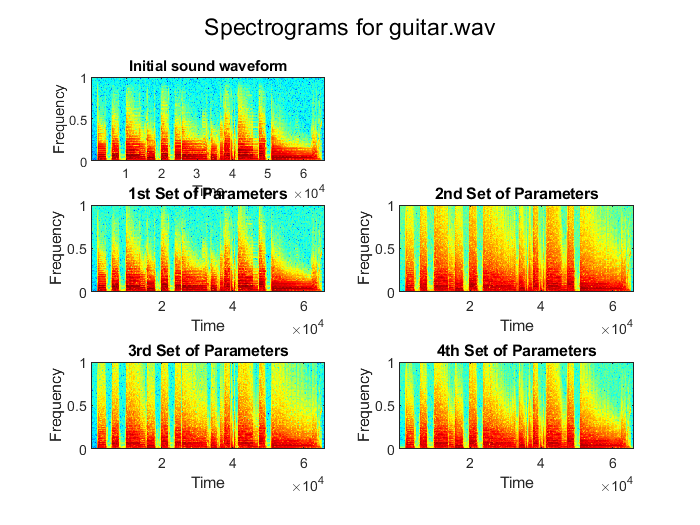


% Add titles to subplots
title(s0, 'Initial sound waveform')
title(s1, '1st Set of Parameters') 
title(s2, '2nd Set of Parameters')
title(s3, '3rd Set of Parameters')
title(s4, '4th Set of Parameters')

figure
% Uncomment to listen the result
% soundsc(x2,16000);
% soundsc(results2(:,1),16000);
% soundsc(results2(:,2),16000);
% soundsc(results2(:,3),16000);
% soundsc(results2(:,4),16000);

**Συνάρτηση tube_dist()**

Η συνάρτηση tube_dist() υλοποιεί τη λειτουργία του εφέ tube distortion. Δέχεται ως ορίσματα τα x,Q, dist,gain και η έξοδος της είναι το παραμορφωμένο σήμα. H λειτουργία της συνάρτησης συνοψίζεται στα ακόλουθα υποστάδια:

- κανονικοποίηση του αρχικού ηχητικού σήματος στο [-1,1]

- πολλαπλασιασμός του κανονικοποιημένου σήματος με το gain

- χρήση της συνάρτησης

- κανονικοποίηση της εξόδου στο διάστημα [-1,1]

Η συνάρτηση επιστρέφει ένα διάνυσμα που αποτελεί το παραμορφωμένο με το εφέ tube ηχητικό σήμα.

**Αποτελέσματα**

Εισάγοντας το εφέ στο αρχικό σήμα με διαφορετικές παραμέτρους Q, dist,gain έχουμε τη δυνατότητα να παρατηρήσουμε τη συμπεριφορά που έχει το εφέ στο αρχικό σήμα. Πιο συγκεκριμένα, όπως φαίνεται από τα παραπάνω φασματογραφήματα σε όλα τα σετ παραμέτρων που εφαρμόστηκαν το παραμορφωμένο σήμα εμφανίζει επιπλέον αρμονικές συνιστώσες από το αρχικό και χαρακτηρίζεται από πιο "πλούσιο" συχνοτικό περιεχόμενο. Χαρακτηριστικά, λοιπόν, είναι εμφανές ότι στο φασματογράφημα του δεύτερου σετ παραμέτρων του αρχείου guitar1.wav έχουν υποστεί αλλοίωση περισσότερες συχνότητες από ότι για μικρότερο gain που περιλαμβάνει το πρώτο σετ παραμέτρων.Αντίστοιχα, στο δεύτερο αρχείο ήχου μεγαλύτερη αλλοιώση του συχνοτικού περιεχομένου παρατηρείται στο τρίτο σετ παραμέτρων. Αναφορικά με το τέταρτο σετ παραμέτρων που διαφοροποείται από τα υπόλοιπα τρία παρατηρούμε ότι στο αρχείο guitar1.wav δεν εμφανίζει σημαντική παραμόρφωση συγκριτικά με το δεύτερο σετ παραμέτρων, κάτι που γίνεται ορατό και στο δεύτερο αρχείο ήχου.

Σε κάθε περίπτωση, όμως, και στα δύο αρχεία ήχου παρατηρούνται διαφορές στα φασματογραφήματα πριν και μετά την εφαρμογή του εφέ, καθώς όλα τα φασματογραφήματα που αφορούν το εφέ εμφανίζουν πρόσθετες ή αλλοιωμένες συχνότητες από το αρχικό σήμα. Το γεγονός αυτό γίνεται και ηχητικά αντιληπτό τόσο στο πρώτο όσο και στο δεύτερο αρχείο ήχου και για αυτό άλλωστε γίνεται ευρεία χρήση του συγκεκριμένου εφέ στη μουσική.

### **Ερώτημα Β**

Το δεύτερο ερώτημα αφορά το εφέ rotary. Αποσκοπεί στην υλοποίηση μιας ρουτίνας που πραγματοποιεί τη λειτουργία του rotary speaker, καθώς και στον εντοπισμό των διαφορών που παρατηρούνται στα τελικά ηχητικά σήματα για τις διάφορες παραμέτρους του εφέ.

Ακολουθεί ο κώδικας για τον καθορισμό των παραμέτρων και την εφαρμογή του εφέ:

% Parameters Declaration
M1 = [800, 650];
M2 = [500, 400];
Depth1 = [80, 65];
Depth2 = [50, 40];
f1 = [1.06, 0.9];
f2 = [0.88, 0.5];
fs = 16000;
dim_x1 = size(x1);
y_rotary_L = zeros(dim_x1(1),2);
y_rotary_R = zeros(dim_x1(1),2);

% Compute left and right rotary output
for i=1:2
    [y_rotary_L(:,i), y_rotary_R(:,i)] = rotary(x1,M1(i), M2(i), Depth1(i), Depth2(i), f1(i), f2(i), fs);
end

mat_11 =          0
         0
   -0.3052
         0
         0
   -0.3052
    0.6104
         0
    0.3052
   -0.3052


mat_12 =          0
         0
   -0.3052
         0
         0
   -0.3052
    0.6104
         0
    0.3052
   -0.3052


mat_21 =          0
         0
   -0.3052
         0
         0
   -0.3052
    0.6104
         0
    0.3052
   -0.3052


mat_22 =          0
         0
   -0.3052
         0
         0
   -0.3052
    0.6104
         0
    0.3052
   -0.3052


mat_11 =          0
         0
   -0.3052
         0
         0
   -0.3052
    0.6104
         0
    0.3052
   -0.3052


mat_12 =          0
         0
   -0.3052
         0
         0
   -0.3052
    0.6104
         0
    0.3052
   -0.3052


mat_21 =          0
         0
   -0.3052
         0
         0
   -0.3052
    0.6104
         0
    0.3052
   -0.3052


mat_22 =          0
         0
   -0.3052
         0
         0
   -0.3052
    0.6104
         0
    0.3052
   -0.3052


Στη συνέχεια, συνδυάζουμε με πρόσθεση τις εξόδους με τα δύο σετ τιμών:

% Combine both to get the final result
y_final_L = y_rotary_L(:,1) + y_rotary_L(:,2);
y_final_R = y_rotary_R(:,1) + y_rotary_R(:,2);

% Uncomment to listen to final result
% soundsc([y_final_L, y_final_R],16000);
% soundsc([y_rotary_L(:,1), y_rotary_R(:,1)],16000);
% soundsc([y_rotary_L(:,2), y_rotary_R(:,2)],16000);

Επαναλαμβάνουμε την παραπάνω διαδικασία για το αρχείο ήχου vocals.wav:

% For vocals.wav:
% Parameters Declaration
M1 = [800, 650];
M2 = [500, 400];
Depth1 = [80, 65];
Depth2 = [50, 40];
f1 = [1.06, 0.9];
f2 = [0.88, 0.5];
fs = 16000;
dim_x2 = size(x2);
y2_rotary_L = zeros(dim_x2(1),2);
y2_rotary_R = zeros(dim_x2(1),2);

% Compute left and right rotary output
for i=1:2
    [y2_rotary_L(:,i), y2_rotary_R(:,i)] = rotary(x2,M1(i), M2(i), Depth1(i), Depth2(i), f1(i), f2(i), fs);
end

mat_11 =    -0.0000
   -0.0027
   -0.0104
   -0.0098
   -0.0099
   -0.0090
   -0.0087
   -0.0091
   -0.0091
   -0.0087


mat_12 =    -0.0000
   -0.0027
   -0.0104
   -0.0098
   -0.0099
   -0.0090
   -0.0087
   -0.0091
   -0.0091
   -0.0087


mat_21 =    -0.0000
   -0.0027
   -0.0104
   -0.0098
   -0.0099
   -0.0090
   -0.0087
   -0.0091
   -0.0091
   -0.0087


mat_22 =    -0.0000
   -0.0027
   -0.0104
   -0.0098
   -0.0099
   -0.0090
   -0.0087
   -0.0091
   -0.0091
   -0.0087


mat_11 =    -0.0000
   -0.0027
   -0.0104
   -0.0098
   -0.0099
   -0.0090
   -0.0087
   -0.0091
   -0.0091
   -0.0087


mat_12 =    -0.0000
   -0.0027
   -0.0104
   -0.0098
   -0.0099
   -0.0090
   -0.0087
   -0.0091
   -0.0091
   -0.0087


mat_21 =    -0.0000
   -0.0027
   -0.0104
   -0.0098
   -0.0099
   -0.0090
   -0.0087
   -0.0091
   -0.0091
   -0.0087


mat_22 =    -0.0000
   -0.0027
   -0.0104
   -0.0098
   -0.0099
   -0.0090
   -0.0087
   -0.0091
   -0.0091
   -0.0087



% Combine both to get the final result
y2_final_L = y2_rotary_L(:,1) + y2_rotary_L(:,2);
y2_final_R = y2_rotary_R(:,1) + y2_rotary_R(:,2);

% Uncomment to listen to final result
% soundsc([y2_final_L, y2_final_R],16000);
% soundsc([y2_rotary_L(:,1), y2_rotary_R(:,1)],16000);
% soundsc([y2_rotary_L(:,2), y2_rotary_R(:,2)],16000);

**Συνάρτηση rotary()**

Η συνάρτηση rotary() υλοποιεί το ψηφιακό εφέ rotary. Λαμβάνει ως εισόδους τις μεταβλητές `x, M1, M2, depth1, depth2, f1, f2, fs και η έξοδος της είναι το [y_L,y_R]. Η έξοδος υπολογίζεται από τις εξισώσεις που περιγράφουν το ακόλουθο κύκλωμα:`

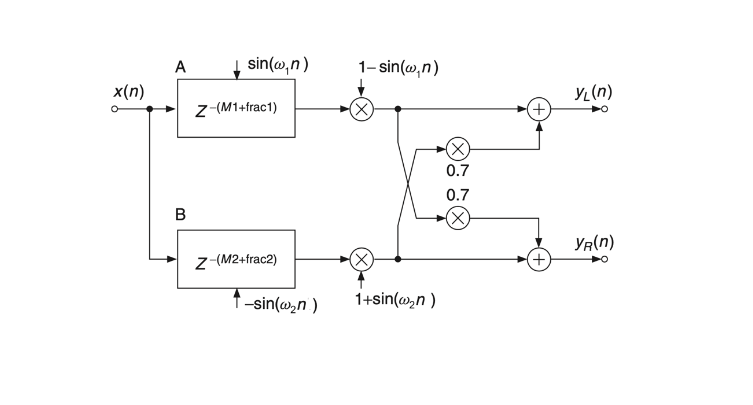

img = imread('rotary_speaker_circuit.png');
imshow(img)

Η χρήση των εξισώσεων διαφορών απαιτεί τον υπολογισμό της καθυστέρησης, η οποία είναι δυναμική και διαφορετική ανά δείγμα. Για τον υπολογισμό της καθυστέρησης με χρήση των παραμέτρων της συνάρτησης rotary() έχει υλοποιηθεί η συνάρτηση find_delay(). Σε κάθε στάδιο της επαναληπτικής διαδικασίας, λοιπόν, καλείται η παραπάνω συνάρτηση για την εύρεση της καθυστέρησης κάθε κλάδου και στη συνέχεια με χρήση τον εξισώσεων διαφορών του συστήματος υπολογίζεται η τελική έξοδος. Η συνάρτηση επιστρέφει τα σήματα εξόδου των δύο κλάδων του συστήματος.

**Αποτελέσματα**

Στην παραπάνω άσκηση εξάγουμε τους δύο κλάδους εξόδου από το σύστημα που προσομοιώνει το rotary speaker και προσπαθούμε να πάρουμε καλύτερο αποτέλεσμα με συνδυασμό των εξόδων με τα δύο σετ τιμών μέσω πρόσθεσης. Με χρήση των εξόδων και των δύο σετ τιμών προσομοιώνεται η λειτουργία τόσο του άνω όσο και του κάτω μέρους ενός rotary speaker. Έτσι, ηχητικά παρατηρούμε σαν να εναλλάσεται το βάθος μεταξύ των δύο σετ σημάτων, με αποτέλεσμα να αλληλοσυμπληρώνονται και να δίνουν έτσι το τελικό ηχητικά πλήρες σήμα.

Ακούγοντας το αποτέλεσμα με χρήση του ενός σετ τιμών και με συνδυασμό των δύο σετ τιμών μπορούμε να πούμε ότι παρότι τα δύο σήματα μοιάζουν αρκετά ηχητικά στη δεύτερη περίπτωση το ηχητικό αποτέλεσμα είναι "πληρέστερο". Βέβαια, αυτό εμπίπτει και στην υποκειμενική αίσθηση ακοής του κάθε ατόμου. Σε κάθε περίπτωση το ηχητικό εφέ rotary μπορεί να γίνει αντιληπτό και στα δύο αρχεία ήχου.

### **Ερώτημα Γ**

Το τρίτο ερώτημα αφορά στην υλοποίηση Schroeder reverberator. Συγκεκριμένα, η χρήση της συνάρτησης reverb_schroeder() προσομοιώνει το εφέ με δυνατότητα επιλογής της διάταξης που θα χρησιμοποιηθεί για την παραγωγή του. Ελέγχουμε τις αλλαγές που επιφέρει το εφέ για διάφορες τιμές των παραμέτρων mix και για τις δύο τοπολογίες κυκλωμάτων:

% For guitar1.wav we test different values of parameters:
mix = 1;
type = 1;
y_schroeder = zeros(1,16000);
y_schroeder = reverb_schroeder(x1,type, mix);

% Uncomment to listen the result
% soundsc(y_schroeder,16000);

% Check result for mix=0.4
mix = 0.4;
type = 1;
y_schroeder = reverb_schroeder(x1,type, mix);

% Uncomment to listen the result
% soundsc(y_schroeder,16000);

% Check result for type=2
mix = 1;
type = 2;
y_schroeder = reverb_schroeder(x1,type, mix);

FFCF_total =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% Uncomment to listen the result
% soundsc(y_schroeder,16000);

% Check result for type=2 & mix=0.4
mix = 0.4;
type = 2;
y_schroeder = reverb_schroeder(x1,type, mix);

FFCF_total =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% Uncomment to listen the result
% soundsc(y_schroeder,16000);

Στη συνέχεια, επαναλαμβάνουμε την παραπάνω διαδικασία για τον έλεγχο της επίδρασης του εφέ στο δεύτερο αρχείο ήχου:

% For vocals.wav:
mix = 1;
type = 1;
y_schroeder_2 = zeros(1,16000);
y_schroeder_2 = reverb_schroeder(x2,type, mix);

% Uncomment to listen the result
% soundsc(y_schroeder_2,16000);

% Check result for mix=0.4
mix = 0.4;
type = 1;
y_schroeder_2 = reverb_schroeder(x2,type, mix);

% Uncomment to listen the result
% soundsc(y_schroeder_2,16000);

% Check result for type=2
mix = 1;
type = 2;
y_schroeder_2 = reverb_schroeder(x2,type, mix);

FFCF_total =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% Uncomment to listen the result
% soundsc(y_schroeder_2,16000);

% Check result for mix=0.4 & type = 2
mix = 0.4;
type = 2;
y_schroeder_2 = reverb_schroeder(x2,type, mix);

FFCF_total =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% Uncomment to listen the result
% soundsc(y_schroeder_2,16000);

**Συνάρτηση reverb_schroeder()**

Με την παρούσα συνάρτηση υλοποιούμε το ψηφιακό εφέ reverb schroeder. Η συνάρτηση καλεί 3 άλλες συναρτήσεις, οι οποίες είναι οι: AP(), FFCF(), FBCF() και αντιστοιχούν στην υλοποίηση ολοπερατών φίλτρων, Feed-Forward Comb Filters και Feed-Back Comb Filters. Αξίζει, επίσης, να σημειωθεί ότι η παρούσα υλοποίηση δίνει τη δυνατότητα για επιλογή της "αρχιτεκτονικής" του κυκλώματος που θα δημιουργήσει το εφέ. Με άλλα λόγια, ανάλογα με την τιμή της μεταβλητής type μπορεί να επιλεγεί μία από τις δύο "αρχιτεκτονικές" που παρέχονται. Σε κάθε περίπτωση το τελικό σήμα με το εφέ επιστρέφεται από τη συνάρτηση μαζί με το αντίθετο του.

**Αποτελέσματα**

Στο ερώτημα αυτό υλοποιήθηκαν δύο εκδοχές του Schroeder reverberator και έγινε έλεγχος και σύγκριση των αποτελεσμάτων για δύο τιμές της παραμέτρου mix. Πιο συγκεκριμένα, όπως γνωρίζουμε, το mix καθορίζει το ποσοστό του αρχικού σήματος που θα εμφανιστεί στην παραμορφωμένη έξοδο. Μικρότερες τιμές, λοιπόν, της παραμέτρου mix έχουν ως αποτέλεσμα το τελικό σήμα να ακούγεται πιο όμοιο με το αρχικό, ενώ μεγαλύτερες τιμές του mix κάνουν πιο έντονη την παρουσία της παραμόρφωσης που εισάγει το εφέ. Η διαφορά αυτή είναι αντιληπτή ακουστικά και στα δύο αρχεία ήχου.

Αναφορικά με τις δύο τοπολογίες κυκλωμάτων που επιλέγονται από την παράμετρο type αξίζει να σημειώσουμε ότι οδηγούν σε παρόμοια ηχητικά αποτελέσματα και στα δύο αρχεία ήχου. Ακούγοντας το ηχητικό αποτέλεσμα μπορούμε να πούμε ότι στη δεύτερη τοπολογία το αποτέλεσμα είναι λίγο πιο "ανάλαφρο" και "καθαρό". Όπως έχουμε σημειώσει και ανωτέρω, όμως, αυτό εξαρτάται και από τα υποκειμενικά χαρακτηριστικά της ακοής κάθε ανθρώπου και επομένως δεν αποτελεί απαραίτητα κοινή  θέση για όλα τα άτομα.